# Plot the Poynting vector in Fourier space of the SFG scattered field

clear;
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL');
addpath(genpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\analysis'));
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config');
addpath(genpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\jobs\completed'));
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\jobs\completed\NotProcessed');


if false
    freq_num = 16;
    cylinder_dimer_no_substrate_110_13 = ["cylinder_dimer_no_substrate_110_13_1",...
        "cylinder_dimer_no_substrate_110_13_2","cylinder_dimer_no_substrate_110_13_3",...
        "cylinder_dimer_no_substrate_110_13_4","cylinder_dimer_no_substrate_110_13_5",...
        "cylinder_dimer_no_substrate_110_13_6"];
    cylinder_dimer_no_substrate_111_28 = ["cylinder_dimer_no_substrate_111_28_1",...
        "cylinder_dimer_no_substrate_111_28_2","cylinder_dimer_no_substrate_111_28_3",...
        "cylinder_dimer_no_substrate_111_28_4","cylinder_dimer_no_substrate_111_28_5",...
        "cylinder_dimer_no_substrate_111_28_6"];
else
    freq_num = 25;
    cylinder_dimer_no_substrate_110_13 = ["cylinder_dimer_no_substrate_110_13_7",...
        "cylinder_dimer_no_substrate_110_13_8","cylinder_dimer_no_substrate_110_13_9",...
        "cylinder_dimer_no_substrate_110_13_11","cylinder_dimer_no_substrate_110_13_12",...
        "cylinder_dimer_no_substrate_110_13_13"];
    cylinder_dimer_no_substrate_111_28 = ["cylinder_dimer_no_substrate_111_28_7",...
        "cylinder_dimer_no_substrate_111_28_8","cylinder_dimer_no_substrate_111_28_9",...
        "cylinder_dimer_no_substrate_111_28_11","cylinder_dimer_no_substrate_111_28_12",...
        "cylinder_dimer_no_substrate_111_28_13"];
end
slab_no_substrate_100 = ["slab_no_substrate_100_1" "slab_no_substrate_100_2",...
        "slab_no_substrate_100_3"];
slab_no_substrate_110 = ["slab_no_substrate_110_1" "slab_no_substrate_110_2",...
        "slab_no_substrate_110_3"];
slab_no_substrate_111 = ["slab_no_substrate_111_1" "slab_no_substrate_111_2",...
        "slab_no_substrate_111_3"];
    
freq_num = 13;
cylinder_dimer_no_substrate_111_34_crosspol = ["cylinder_dimer_no_substrate_111_34_7",...
    "cylinder_dimer_no_substrate_111_34_8","cylinder_dimer_no_substrate_111_34_9",...
    "cylinder_dimer_no_substrate_111_34_16","cylinder_dimer_no_substrate_111_34_17",...
    "cylinder_dimer_no_substrate_111_34_18","cylinder_dimer_no_substrate_111_34_13",...
    "cylinder_dimer_no_substrate_111_34_11","cylinder_dimer_no_substrate_111_34_12"];
cylinder_dimer_no_substrate_111_34_copol = ["cylinder_dimer_no_substrate_111_34_19",...
    "cylinder_dimer_no_substrate_111_34_20","cylinder_dimer_no_substrate_111_34_21",...
    "cylinder_dimer_no_substrate_111_34_22","cylinder_dimer_no_substrate_111_34_23",...
    "cylinder_dimer_no_substrate_111_34_24","cylinder_dimer_no_substrate_111_34_25",...
    "cylinder_dimer_no_substrate_111_34_26","cylinder_dimer_no_substrate_111_34_27"];

%for job = cylinder_dimer_no_substrate_111_28
for job = cylinder_dimer_no_substrate_111_34_crosspol
    eval(job);
    load([options.output_dir_final 'cut_plane\sum_fft.mat']);
    extra_options = matthew_extra_options(options);
    

Do the FFT on both Near field and Farfield cut planes.

freq_num = 13


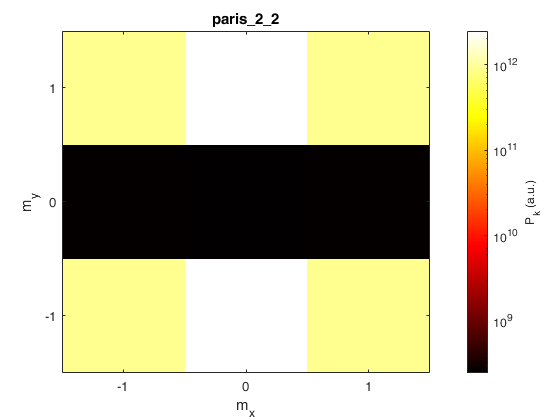

    for cut_plane_index = 1:length(extra_options.cut_plane)
        for direction = extra_options.direction
            for theta_num=extra_options.plot_theta_nums
                %for freq_num = 16%extra_options.plot_freq_nums
                    
                    [FTx, FTy, FTz,FThx, FThy, FThz, FTpoynting] = ...
                        matthew_get_fft_of_cut_plane(sum_fft, ...
                        extra_options.cut_plane(cut_plane_index), direction, freq_num);
                    
                    for FT_num = 5%1:5
                        switch FT_num
                            case 1
                                FTxyz = FTx;
                                FThxyz = FThx;
                            case 2
                                FTxyz = FTy;
                                FThxyz = FThy;
                            case 3
                                FTxyz = FTz;
                                FThxyz = FThz;
                            case 4
                                FTxyz = abs(FTx).^2 + abs(FTy).^2;
                                FThxyz = abs(FThx).^2 + abs(FThy).^2;
                            otherwise
                                FTxyz = FTpoynting;
                        end
                            
                        [X,Y] = meshgrid(...
                            -2/pi-4/(pi*(length(FTxyz)-1)):4/(pi*(length(FTxyz)-1)):...
                                    2/pi-4/(pi*(length(FTxyz)-1)),...
                            -2/pi-4/(pi*(length(FTxyz)-1)):4/(pi*(length(FTxyz)-1)):...
                                    2/pi-4/(pi*(length(FTxyz)-1)));
                                
                        fprintf('freq_num = %d\n', freq_num);
                        fig = figure;
                        imagesc(abs(FTxyz));
                        view(0,-90);
                        xlabel('m_x')
                        ylabel('m_y')
                        xticks([1 2 3]);
                        xticklabels({'-1','0','1'});
                        yticks([1 2 3]);
                        yticklabels({'-1','0','1'});
                        cb = colorbar;
                        set(gca,'ColorScale','log');
                        ylabel(cb, 'P_k (a.u.)');
                        switch FT_num
                            case 1
                                title('|FFT(E_x)|');
                            case 2
                                title('|FFT(E_y)|');
                            case 3
                                title('|FFT(E_z)|');
                            case 4
                                title('|FFT(E_x)|^2+|E_y|^2');
                            otherwise
                                title(job, 'Interpreter', 'none');
                        end
                        colormap hot;
                        axis tight;
                        saveas(fig, strcat("C:\Users\Matthew\Downloads\",job, "_fft_all_orders"), 'png');
                    end
                %end
            end
        end
    end
end